# Simulating the 5G NR PDSCH with Multi-Process HARQ

In the previous lab, we created a simple frequency-domain channel along with a gNB TX and UE RX to simulate the downlink data processing.  In this lab, we will build on the results in that lab to add multi-process Hybrid ARQ.  The [MATLAB's 5G Toolbox](https://www.mathworks.com/help/5g/index.htm)  has excellent tools to simulate complete 5G NR HARQ processes.

In going through the lab, you will learn to:

- Create PDSCH allocations for a subset of the RBs

- Measure the time-varying wideband SNR and the SNR on a subset of the resource blocks (RBs)

- Encode and decode data with HARQ using MATLAB 5G Toolbox tools

- Create a simple multi-process TX and RX

- Evaluate the performance of the link with HARQ on a fading channel

Some of the code in this lab is based on  [MATLAB's PDSCH throuhput demo](https://www.mathworks.com/help/5g/ug/nr-pdsch-throughput.html).  You will need to get the R2020B version of MATLAB's 5G Toolbox for the demo.  The Toolbox is rapidly evolving, and I have used some functions that are not available in R2020A.  Also, along with this file, you will see three other files:

- `FDChan.m`:  A class for frequency-domain channel simulation

- `NRgNBTxFD.m`:  A class for NR gNB TX frequency-domain simulation

- `NRUERxFD.m`:  A class for NR UE RX frequency-domain simulation

These files have some TODO sections to be completed.

**Submission**:  Complete this MATLAB live file and the other files.  Run the code.  Print all the files to PDF.  Merge to a single PDF and submit the PDF for grading.

## Configuring the System Prameters

In this lab, we will configure the parameters with the following parameters.

fc = 2.3e9;                % Carrier frequency
SubcarrierSpacing = 15;    % SCS in kHZ
NRB = 51;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

Using the SCS and number of resource blocks, compute and print the bandwidth occupied by this waveform.

% TODO:
bwMHz = NRB*nscPerRB*SubcarrierSpacing/1e3; 
fprintf(1, 'The bandwidth in [MHz] = %.2f\n', bwMHz);

The bandwidth in [MHz] = 9.18


Similar to the previous lab, get the `carrierConfig` and `waveformConfig` with the `nrCarrierConfig` and `nrOFDMInfo` methods in the 5G Toolbox.

% TODO
carrierConfig = nrCarrierConfig("NSizeGrid",NRB,"SubcarrierSpacing",SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

## Configuring a Frequency-Domain OFDM Channel

We will simulate the channel with the following paths.

- `npaths=10` paths

- Set the `gain` so that they all have 0 dB relative gain

- Set `dly` so that the path delays are exponentially distributed with mean 50ns

- Set aoaAz to have paths with uniform angles from [0,360] degrees

- Set `aoaEl `to have uniform angles from [-20,20] degrees

% Number of paths
npaths = 10;

% TODO:  Set parmaeters for each path
gain = zeros(npaths,1);
dly = exprnd(50e-9,npaths,1);
aoaAz = rand(npaths,1)*360;
aoaEl = -20 + 40*rand(npaths,1);

Once you create these paths, you can create a frequency-domain channel using the `FDChan` object I have included.

% Mobile velocity vector in m/s
rxVel = [5,0,0]';

% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
EsN0Avg = 10;   % Average SNR
 
% Create a FD channel
fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', fc);

## Simulating the Frequency-Domain Channel

The frequency-domain channel has the identical syntax as the the previous lab as well as the demo.  We first observe one realization of the channel in one slot.

We first create a grid of TX symbols.  For now, we will just set them all to ones.

NumLayers = 1;
txGrid = nrResourceGrid(carrierConfig, NumLayers);
txGrid(:) = 1;

Set the `frameNum=0 and slotNum=0 `and call the `fdchan.step()` method to get the channel grid and noise variance.  Compute a channel SNR matrix, `chanSnr(i,j) `representing the SNR in dB per RE.  Plot `chanSnr` with the `imagesc` command.  You should see some frequency selective fading.  But, minimal fast fading.

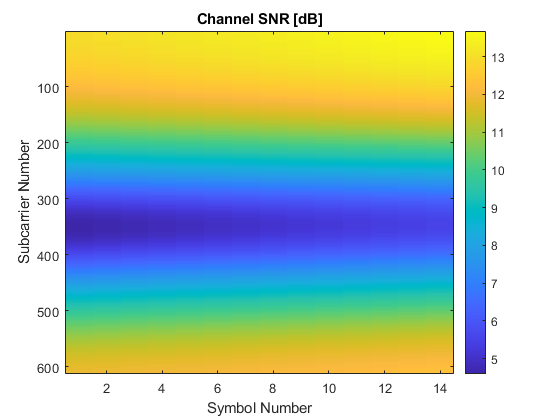

frameNum = 0;
slotNum = 0;

% TODO:  
[~, chanGrid, noiseVar] = fdchan.step(txGrid, frameNum, slotNum);
figure;
imagesc(1:carrierConfig.SymbolsPerSlot, 1:NRB*nscPerRB, pow2db(abs(chanGrid).^2/noiseVar));
ylabel("Subcarrier Number"); xlabel("Symbol Number");
title("Channel SNR [dB]");
colorbar();

## Examining the Channel on a PDSCH With a Limited Frequency-Domain Allocation

We introduced PDSCH allocations in the previous lab.   An additional feature of PDSCH allocations is that they can be on a subset of the RBs.  This sort of allocation is often necessary if the gNB needs to schedule multiple UEs in the same time slot.  In this section, we consider PDSCH allocations on a set of contiguous RBs:

`    ind,...,ind+NRBPdsch-1`

where

NRBPdsch = 20;

Before we configure this PDSCH, complete the following code to compare how the channel SNR varies over this time in the whole band, and in the PDSCH allocation.  Specifically, we run a simulation of the frequency-domain channel over slots `islot=1,...,nslots`. For each slot, we compute:

- `chanSnrWideband(islot)` = average SNR across the whole band 

- `chanSnrPdschFix(islot)` = average SNR across PDSCH allocation with a fixed starting index, `ifix=0`.

- `chanSnrPdschRnd(islot)` = average SNR across PDSCH allocation with a random starting index, `irnd.`

You should see that there the fixed PDSCH allocation has more overall variability since it is on a smaller bandwidth.  The random allocation has the same total variability but fluctuates more from one slot to the next.  This property is useful for diversity.

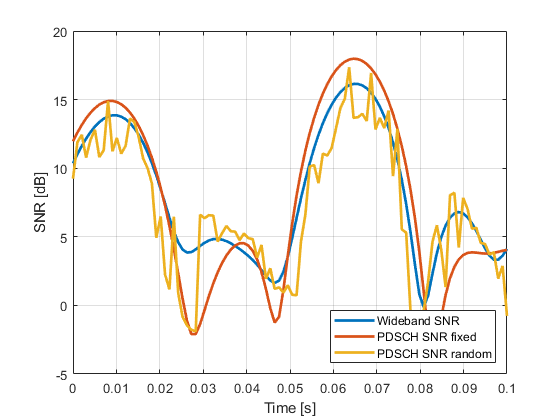

% Number of slots for the simulation
nslots = 100;

% SNR measurements per slot
chanSnrWideband = zeros(nslots,1);     % Avg SNR across the whole band
chanSnrPdschFix = zeros(nslots,1);     % Avg SNR across a fixed PDSCH allocation
chanSnrPdschRnd = zeros(nslots,1);     % Avg SNR across a random PDSCH allocation

for islot = 1:nslots
    
    % TODO:  Get the slot and frame number
    slotNum = mod(islot-1,carrierConfig.SlotsPerFrame);
    frameNum = floor((islot-1)/carrierConfig.SlotsPerFrame);
    
    % TODO:  Get the channel and noise variance in the slot
    [~, chanGrid, noiseVar] = fdchan.step(txGrid, frameNum, slotNum);
    
    % TODO:  Compute the average SNR in the channel
    chanSnr = mean(abs(chanGrid).^2/noiseVar, 2);
    
    % Set the fixed allocation to start an PRB index = 0
    ifix = 0;
    
    % TODO:  Select a random start index for the random allocation
    %    irnd = 0,..., NRB-NRBPdsch-1
    irnd = randi([0 NRB-NRBPdsch-1],1,1);
    
    % TODO:  Compute the average SNR over the full band, 
    % the average SNR on a fixed PDSCH allocation and 
    % the average SNR on a random PDSCH allocation.
    chanSnrWideband(islot) = mean(chanSnr);
    chanSnrPdschFix(islot) = mean(chanSnr(ifix+1:NRBPdsch*nscPerRB));
    chanSnrPdschRnd(islot) = mean(chanSnr(irnd*nscPerRB+1:irnd*nscPerRB+NRBPdsch*nscPerRB));
end

% Convert to dB
chanSnrWideband = pow2db(chanSnrWideband);    
chanSnrPdschFix = pow2db(chanSnrPdschFix);
chanSnrPdschRnd = pow2db(chanSnrPdschRnd);
% TODO:  Plot the SNR vs. time in seconds.
figure;
numFrames = nslots/carrierConfig.SlotsPerFrame;
t = linspace(0,numFrames*10e-3,nslots);
plot(t,chanSnrWideband,'LineWidth',2); hold on;
plot(t,chanSnrPdschFix,'LineWidth',2); hold on;
plot(t,chanSnrPdschRnd,'LineWidth',2); hold off;
xlabel("Time [s]"); ylabel("SNR [dB]"); grid on;
legend("Wideband SNR","PDSCH SNR fixed","PDSCH SNR random","Location","southeast");

## Building the TX with HARQ

To make the simulation simple, we will look at a fixed PDSCH allocation.  However, you would get slightly better performance with a randomized allocation.  We will mostly use the same parameters as the previous lab.  The only difference is that we have allocated only the the RBs `(0:NRBPdsch-1)`.  

Modulation = '16QAM';
targetCodeRate = 490/1024;
pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRBPdsch-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'EnablePTRS', 1,...
    'PTRS', nrPDSCHPTRSConfig());

I have created a simple TX with HARQ in the file, `NRgNBTxFd.m. `It is mostly the same as the previous lab.   It requires some small changes to support multiple HARQ processes.  The 5G Toolbox has incredible tools to manage the multiple HARQ processes.   

**Note:**  I have used the indexing `iharq=1,...,nharq.  `But, many of the 5G Toolbox tools use zero indexing.  So you will need to use `iharq-1`.  

% TODO:  Complete the sections labeled TODO in NRgNBTxFD.m

Once you have finished the modifications, you can create the class with the following command.

% number of HARQ processes
nHarq = 8;
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate, 'nharq', nHarq);

You can then call the `step` method to generate random bits for one slot of data based on the PDSCH configuration.  The input is the HARQ process ID you want to use for that slot.  Here we use the first HARQ process.

iharq = 1;
[txGrid, rv, newDat] = tx.step(iharq);

Use the `imagesc` command to plot the set of resource elements in the grid where `txGrid` is non-zero.  These are the resource elements (REs) where the PDSCH channel is allocated.  You should see that the PDSCH is allocated to the top 

- The first OFDM symbol.  This is where the assignment channel, called the PDCCH, will go.  Basically this communicates to the UEs the resource allocation, UE identity in that slot.  We will discuss

- The third OFDM symbol. which is used as demodulation reference signal (DM-RS) used in channel estimation.  We will discuss this when we discuss equalization

- The horizontal strips.  These are PT-RS for phase noise mitigation that we will also discuss later.

% TODO
figure;
imagesc(abs(txGrid)~=0);
ylabel("Subcarrier Number"); xlabel("Symbol Number");
title("Non-zero Resource Grid");
colorbar();

## Building a Simple HARQ RX 

Next, complete the code in `NRUERxFD.m.`  Again, I have created a skeleton that does almost all the work using the 5G Toolbox methods.  It also follows the structure of the previous lab closely.  

% TODO:  Complete the sections labeled TODO in NRUERxFD.m

## Running a HARQ Simulation

We can now run a simple HARQ simulation.   Complete the following code.

% TODO:  Create the RX and TX
rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate, 'nharq', nHarq);
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate, 'nharq', nHarq);

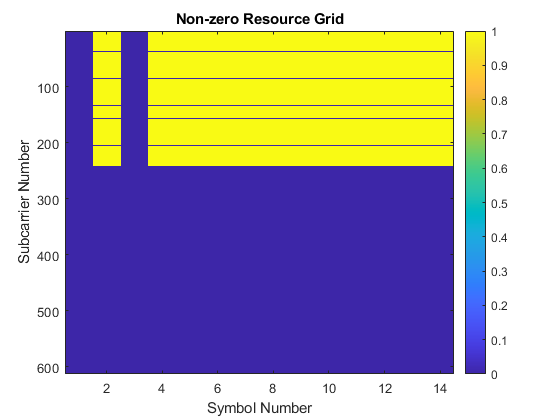

% Create the channel
EsN0Avg = 5;

fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', fc);

% Set the parameters
nslots = 200;
dataRate = zeros(nslots,1);
chanSnrPdsch = zeros(nslots,1);
chanSnrWideband = zeros(nslots, 1);
nharq = 8;

% Loop over the slots
for islot = 1:nslots
    
    % Set the HARQ process ID.  We will use a round-robin selection
    iharq = mod(islot-1, nharq) + 1;
    
    % TODO:  Run the transmitter for one slot
    [txGrid, rv, newDat] = tx.step(iharq);
    
    % TODO:  Get the slot and frame number
    slotNum = mod(islot-1,carrierConfig.SlotsPerFrame);
    frameNum = floor((islot-1)/carrierConfig.SlotsPerFrame);
    
    % TODO:  Run the channel
    [rxGrid, chanGrid, noiseVar] = fdchan.step(txGrid, frameNum, slotNum);
    
    % TODO:  Run the data through the receiver
    rx.step(rxGrid,chanGrid,noiseVar,iharq,rv,newDat);
    
    % Check if data passed    
    nerr = sum(rx.rxBits ~= tx.txBits{iharq}{1});
    
    % If there are on errors
    if nerr == 0
        % Simulate an ACK being sent back to the TX
        tx.setAck(iharq);
        
        % TODO:  Compute data rate for the slot
        rxData = rx.rxBits;
        dataRate(islot) = length(rxData)/1e-3; % numerology 0 (SCS 15 KHz) --> slot duration 1 ms       
    end             
    
    chanSnr = mean(abs(chanGrid).^2/noiseVar, 2);
    % TODO:  Compute the average SNR in the slot
    chanSnrWideband(islot) = mean(chanSnr);
    PRBset = length(pdschConfig.PRBSet);
    chanSnrPdsch(islot) = mean(chanSnr(1:PRBset*nscPerRB));
end
chanSnrPdsch = pow2db(chanSnrPdsch);
txData = tx.txBits;

## Plot the Results

Create two subplots:

- On the top subplot, plot `chanSnrPdsch` vs. time in seconds

- On the bottom subplot, plot the instantaneous data rate, `dataRate` along with a time average data rate.  The time averaged should be a moving window of 16 slots.

% TODO
numFrames = nslots/carrierConfig.SlotsPerFrame;
t = (0:(nslots-1))*1e-3;

dataRate_Mbps = dataRate / 1e6; 
avg_dataRate = movmean(dataRate_Mbps, 16);

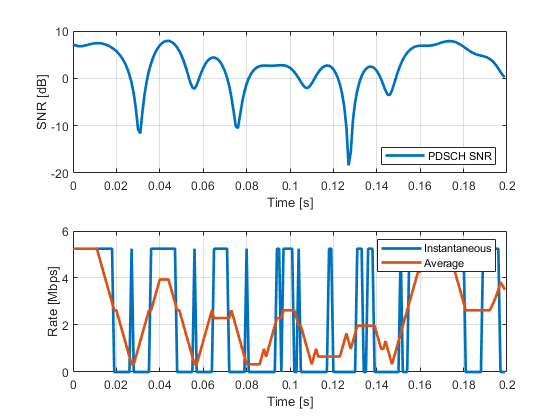

figure;
subplot(2,1,1);
plot(t,chanSnrPdsch,'LineWidth',2);
xlabel("Time [s]"); ylabel("SNR [dB]"); grid on;
legend("PDSCH SNR","Location","southeast");

subplot(2,1,2);
plot(t,dataRate_Mbps, 'LineWidth',2); hold on;
plot(t,avg_dataRate, 'LineWidth',2);
xlabel("Time [s]"); ylabel("Rate [Mbps]"); grid on;
legend("Instantaneous","Average");
hold off;